# Motor Sequence Learning (MSL) - TMR Experiment

Analysis of the behavioral data

% Ella Gabitov (gabitovella@gmail.com), 15 December 2022

## Init

% Regular text interpreter
set(0,'DefaultTextInterpreter','none')

### Data Info

[actfile_dpath, ~, ~] = fileparts(matlab.desktop.editor.getActiveFilename);
[main_dpath, ~, ~] = fileparts(actfile_dpath);

add2path = {...
    fullfile(main_dpath, 'analysis');
    };
for i = 1 : length(add2path)
    addpath(add2path{i});
end

% Path to the directory with data for analysis
data_dpath = fullfile(main_dpath, 'results');


### Subjects for Analysis

% A list of subjects
% The data of each subject is stored in the directory with the same name as the subject identifier

% Get all subjects from the src directory
list_dir = dir(data_dpath);
subjects = {list_dir([list_dir(:).isdir]).name};
subjects(contains(subjects, '.')) = []; % Should not contain dots

% Specify subjects explicitly
% subjects = {...
%     'Subject1'...
%     'Subject2'...
%     'Subject3'...
%     };


## Performance Duration

---


P1_01_A01


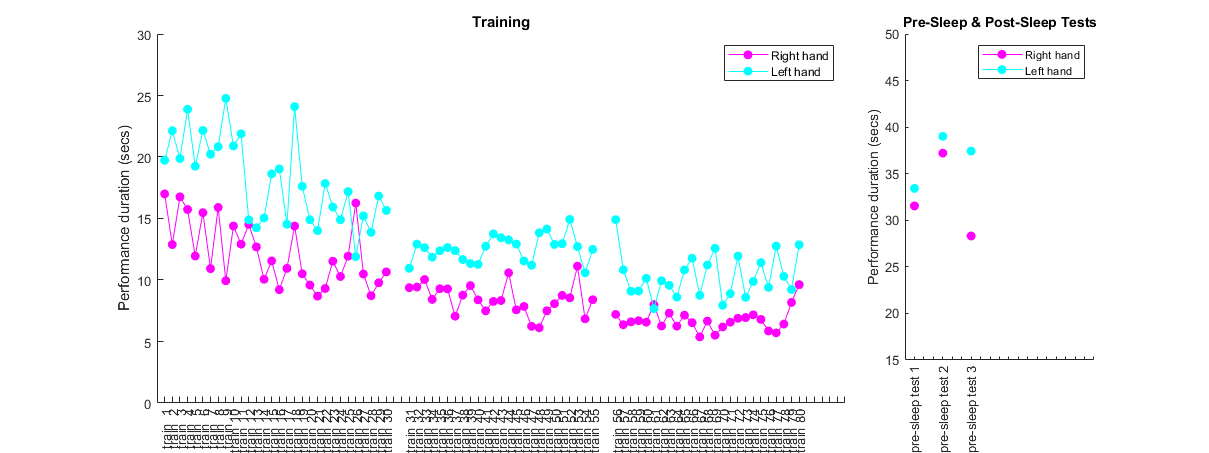

% Plot properties
y_label = 'Performance duration (secs)';

% Sessions for analysis
sessions = {'PreSleep_training', 'PreSleep_test', 'PostSleep_test'};
sess_lbl_length = 20;

init_training = true;
init_tests = true;

for i_subj = 1 : length(subjects)
    subj = subjects{i_subj};
    data_subj_dpath = fullfile(data_dpath, subj);
    disp('---');
    disp(subj);

    % A new figure with two subplots in a single row
    f = figure();
    f_width = 1600; f_height = 600;
    f.Position(3:4) = [f_width, f_height];
    ax_training = subplot(1, 4, [1:3]); % 3/4 of the figure to plot the training data
    ax_tests = subplot(1, 4, 4);

    for i_sess = 1 : length(sessions)
        list_dir = dir(fullfile(data_subj_dpath, [subj, '_', sessions{i_sess}, '*.mat']));
        fnames = {list_dir.name};

        if isempty(fnames)
            continue;
        end

        switch sessions{i_sess}
            case 'PreSleep_training'
                sess_title = 'Training';
                sess_lbl = 'train';

                % Init plot properties for the training session
                if init_training
                    ax2plot = ax_training;

                    x_lim = [0 90];
                    x_ticks = 1:90;
                    x_tick_labels = cell(1, length(x_ticks));
                    x_tick_labels(:) = {''};
                    x_end = 0; % Is used to calculate the next value along the x axis

                    y_lim = [0 30];

                    right_is_labeled = 0;
                    left_is_labeled = 0;

                    init_training = false;

                end

            case 'PreSleep_test'

                sess_title = 'Pre-Sleep & Post-Sleep Tests';
                sess_lbl = 'pre-sleep test';
                
                % Create a new figure
                if init_tests
                    ax2plot = ax_tests;

                    x_lim = [0 20];
                    x_ticks = 1:20;
                    x_tick_labels = cell(1, length(x_ticks));
                    x_tick_labels(:) = {''};
                    x_end = 0; % Is used to calculate the next value along the x axis

                    y_lim = [15 50];

                    right_is_labeled = 0;
                    left_is_labeled = 0;                    

                    init_tests = false;
                end

            case 'PostSleep_test'
                sess_title = 'Pre-Sleep & Post-Sleep Tests';                
                sess_lbl = 'post-sleep test';
        end

        % Add padding to the beginning of the session label
        sess_lbl = pad(sess_lbl, sess_lbl_length - length(sess_lbl), "left");

        % Count blocks to plot
        count_blocks = 0;
        for i_fname = 1 : length(fnames)
            src_fpath = fullfile(data_subj_dpath, fnames{i_fname});
            
            % Load the data
            data_loaded = load(src_fpath);
            blocks_info = data_loaded.blocks.info;
            input_onsets = data_loaded.blocks.input_onsets;

            durations = input_onsets(:, end) - input_onsets(:, 1);

            is_right = strcmp(blocks_info.hand, 'right');
            is_left = strcmp(blocks_info.hand, 'left');

            x = x_end+1 : x_end+length(durations)/2;
            labels = cellstr(strcat(sess_lbl, {' '}, num2str([count_blocks+1 : count_blocks+length(x)]')));
            count_blocks = count_blocks+length(x);
            x_tick_labels(x) = labels;

            subplot(ax2plot);

            % --- PLOT DATA FOR THE RIGHT HAND

            % Magenta color - circle markers - dashed line
            plot_str = 'm o -';
            marker_face_color = 'm';
            
            y_plot = durations(is_right);
            x_plot = x(1:length(y_plot));
            % Add to plot and add the hand label if needed
            if right_is_labeled
                p = plot(x_plot, y_plot, plot_str, 'HandleVisibility', 'off');
            else
                p = plot(x_plot, y_plot, plot_str, 'DisplayName', 'Right hand');
                right_is_labeled = 1;
            end
            p.MarkerFaceColor = marker_face_color;
            box off;
            title(sess_title);
            ylabel(y_label);
            xlim(x_lim);
            ylim(y_lim);
            xticks(x_ticks);
            xticklabels(x_tick_labels);
            legend('show');
            drawnow;
            hold on;

            % --- PLOT DATA FOR THE LEFT HAND

            % Cyan color - circle markers - dashed line
            plot_str = 'c o -'; 
            marker_face_color = 'c';

            y_plot = durations(is_left);
            x_plot = x(1:length(y_plot));            
            
            % Add to plot and add the hand label if needed
            if left_is_labeled
                p = plot(x_plot, y_plot, plot_str, 'HandleVisibility', 'off');
            else
                p = plot(x_plot, y_plot, plot_str, 'DisplayName', 'Left hand');
                left_is_labeled = 1;
            end
            p.MarkerFaceColor = marker_face_color;
            box off;
            title(sess_title);
            ylabel(y_label);
            xlim(x_lim);
            ylim(y_lim);
            legend('show');            
            xticks(x_ticks);
            xticklabels(x_tick_labels);
            drawnow;
            hold on;

            % Add gap before plotting the data for the next phase of the current session
            x_end = x_end + length(x) + 2;

        end

        % Add gap before plotting the data for the next session
        x_end = x_end + 4;

    end

    hold off;

end

## Clear & Close

for i = 1 : length(add2path)
    rmpath(add2path{i});
end

clearvars;
